# File Name: Exercise_02_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Load the point cloud of indoor scene.

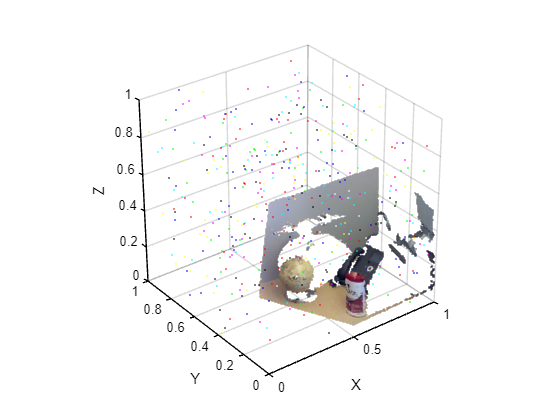

% Load the point cloud of indoor scene which used in the practice.
load('PointCloudwithNoise.mat');

figure;
pcshow(inputCloud);
xlabel('X');
ylabel('Y');
zlabel('Z');
xlim([0, 1]);
ylim([0, 1]);
zlim([0, 1]);
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

## To do 1. Remove a noise of given point cloud.

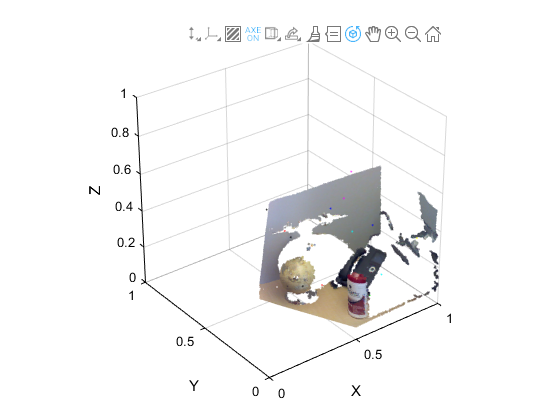

%%%%%%%%%% TODO %%%%%%%%%%
% Point Cloud Denoising with 'pcdenoise'.
denoisedPointCloud = pcdenoise(inputCloud);

figure;
pcshow(denoisedPointCloud);
xlabel('X');
ylabel('Y');
zlabel('Z');
xlim([0, 1]);
ylim([0, 1]);
zlim([0, 1]);
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

w = waitforbuttonpress;

## To do 2. Fit plane to the denoised point cloud.

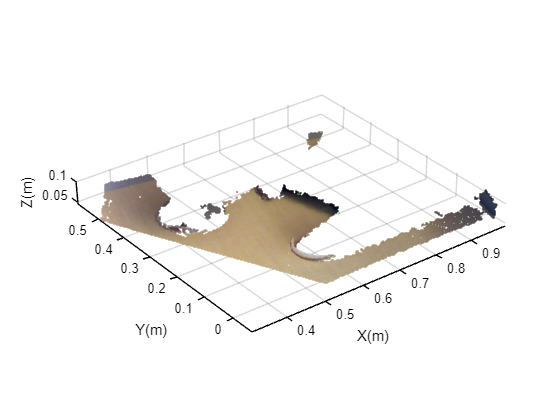

%%%%%%%%%% TODO %%%%%%%%%%
% Fit point cloud to plane
% Set the maximum point-to-plane distance (2cm) for plane fitting.
maxDistance = 0.02;

% Set the normal vector of the plane.
referenceVector = [0,0,1];

% Set the maximum angular distance to 5 degrees.
maxAngularDistance = 5;

% Detect the first plane, the table, and extract it from the point cloud.
[model1,inlierIndices,outlierIndices] = pcfitplane(denoisedPointCloud,...
    maxDistance,referenceVector,maxAngularDistance);
plane1 = select(denoisedPointCloud,inlierIndices);
remaininputCloud = select(denoisedPointCloud,outlierIndices);

% Set the region of interest to constrain the search for the second plane, left wall.
roi = [-inf,inf;0.4,inf;-inf,inf];
sampleIndices = findPointsInROI(remaininputCloud,roi);

% Detect the left wall and extract it from the remaining point cloud.
[model2,inlierIndices,outlierIndices] = pcfitplane(remaininputCloud,...
    maxDistance,'SampleIndices',sampleIndices);
plane2 = select(remaininputCloud,inlierIndices);
remaininputCloud = select(remaininputCloud,outlierIndices);


% Plot the two planes and the remaining points.
figure
pcshow(plane1)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

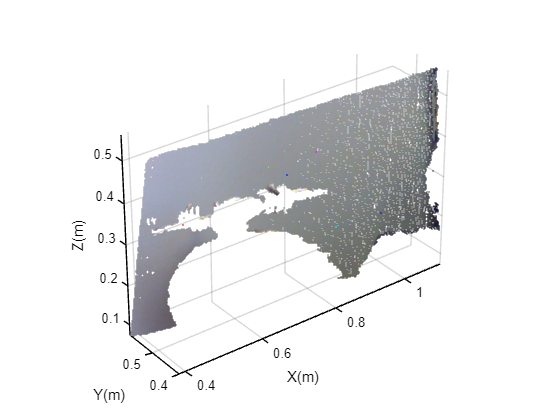


figure
pcshow(plane2)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

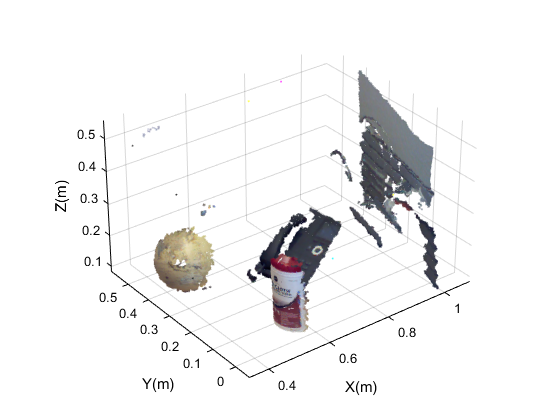


figure
pcshow(remaininputCloud)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])
w = waitforbuttonpress;

## To do 3. Segment the remain point cloud.

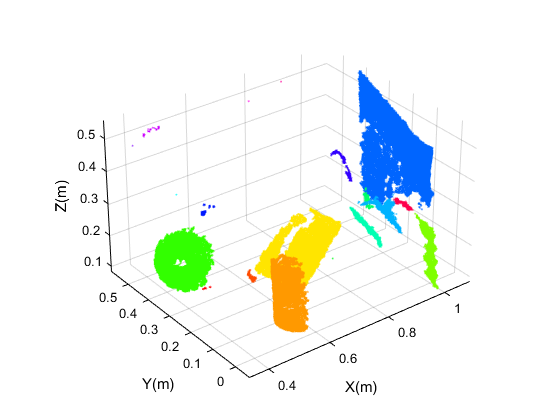

%%%%%%%%%% TODO %%%%%%%%%%
% Specify a minimum Euclidean distance of 0.02 meters between clusters.
distThreshold = 0.02;
[labels,numClusters] = pcsegdist(remaininputCloud,distThreshold);


% Plot the result
figure
pcshow(remaininputCloud.Location,labels)
colormap(hsv(numClusters))
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

w = waitforbuttonpress;

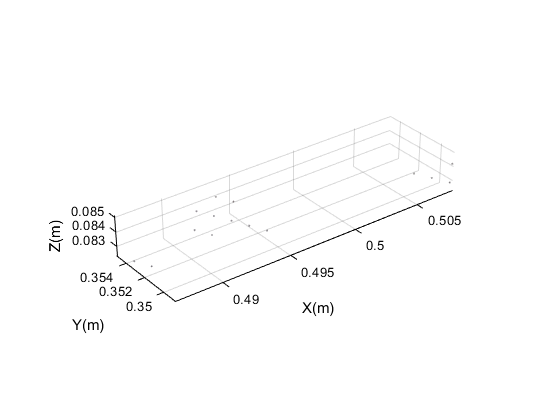

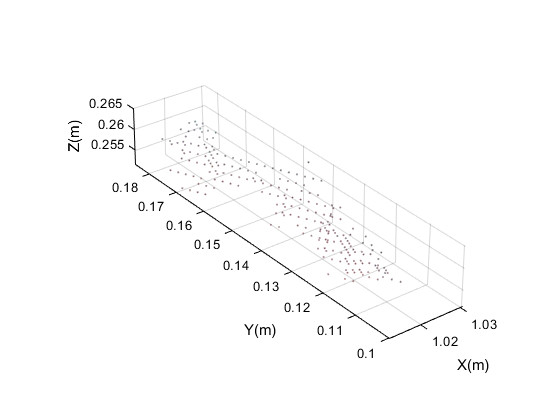

figure

% Point of each cluster
for cluster = 1 : numClusters
    SegementedCluster = select(remaininputCloud,find(labels == cluster));
    
    pcshow(SegementedCluster)
    xlabel('X(m)')
    ylabel('Y(m)')
    zlabel('Z(m)')
    set(gcf,'color','w');
    set(gca,'color','w');
    set(gca, 'XColor', [0. 0. 0.], ...
        'YColor', [0. 0. 0.], ...
        'ZColor', [0. 0. 0.])
    
    w = waitforbuttonpress;
end